# ______________Computational Electromagnetics 

## _______________________________ Hw8-Q2

______________________Mohammadreza Arani         :::::::::::::         810100511

 __________________________________________1401/10/26


clear; clc; close all;

The problem is:

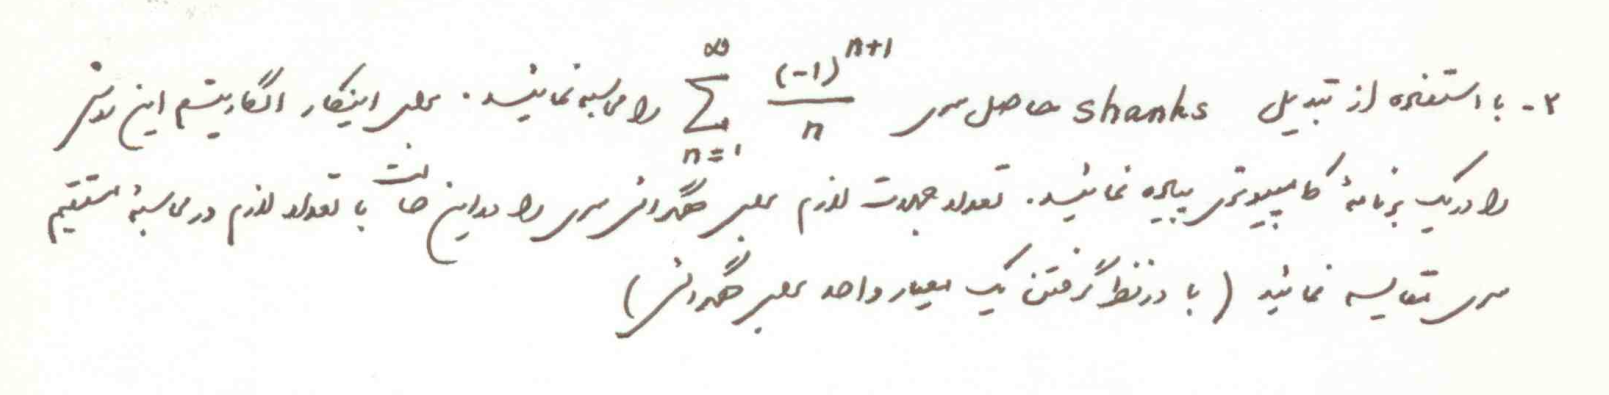

Shanks's Transform formulation is:


$$S=\frac{\left(S_{n+1} *S_{n-1} -S_n^2 \right)}{\left(S_{n+1} +S_{n-1} -2S_n \right)}$$


The series to apply the transform is:


$$\sum_{n=1}^{\infty \;} \frac{{\left(-1\right)}^{n+1} }{\left(n\right)}$$


Max_iter = 1e+04;
cntr=2;

S_n = zeros(1,Max_iter);

while(1)

    S_n(cntr) = S_n(cntr-1) + (-1)^cntr/(cntr-1);

    error = abs(S_n(cntr) - S_n(cntr-1));
    if(error<1e-3)
        break;
    end


    if(cntr>Max_iter)
        break;
    end
cntr = cntr+1;

end

% disp(S_n)

Num_Max = 7;

Keeper = cell(Max_iter,Max_iter);

cntr2 =1;
while(1)
    S_n_T = S_n(1:Num_Max);
    S_n_Temp = S_n_T;
    cntr3 = 0;
    while(1)
        cntr3 = cntr3 +1;
        S_n_Temp = perform_Shanks(S_n_Temp);
        Keeper{cntr2 , cntr3} =  S_n_Temp ;
        if(length(S_n_Temp)<3)
            break;
        end
    end
    
    Prev = cell2mat(Keeper(cntr2,cntr3-2));
    Final = cell2mat(Keeper(cntr2,cntr3-1));

    error_trans   = abs( Final(end)-  Prev(end)  );

    Prev_2 = cell2mat(Keeper(cntr2,cntr3-1));
    Final_2 = cell2mat(Keeper(cntr2,cntr3));

    error_trans_2 = abs( Final_2(end)-  Prev_2(end)  );

    if( (error_trans<1e-3) &&  (error_trans_2<1e-3) )
        break;
    end


    if(cntr2>Max_iter)
        break;
    end

    
    cntr2   = cntr2+1;
    Num_Max = Num_Max+2;
    if(Num_Max>cntr)
        break;
    end


end


disp(S_n(1:Num_Max)'); % Given Series

                   0
   1.000000000000000
   0.500000000000000
   0.833333333333333
   0.583333333333333
   0.783333333333333
   0.616666666666667
   0.759523809523809
   0.634523809523809
   0.745634920634921
   0.645634920634921
   0.736544011544012
   0.653210678210678
   0.730133755133755
   0.658705183705184
   0.725371850371850
   0.662871850371850
   0.721695379783615
   0.666139824228060
   0.718771403175428
   0.668771403175428



disp(     cell2mat(Keeper(cntr2,cntr3-7))'  ); % Generated SHanks Series

   0.693140127374205
   0.693148869333182
   0.693146681971590
   0.693147354031818
   0.693147111911928
   0.693147210655419
   0.693147166238412
   0.693147187892628
   0.693147176565422
   0.693147182765315
   0.693147179326246
   0.693147181431651
   0.693147180247842
   0.693147181001345
   0.693147180604408



disp(     cell2mat(Keeper(cntr2,cntr3-6))'  ); % Generated SHanks Series

   0.693147119737629
   0.693147196108489
   0.693147176120171
   0.693147181988219
   0.693147179616545
   0.693147180970217
   0.693147179603046
   0.693147180810286
   0.693147175736740
   0.693147168094248
   0.693147190988102
   0.693147234477407
   0.693147212628626



disp(     cell2mat(Keeper(cntr2,cntr3-5))'  ); % Generated SHanks Series

   0.693147179506449
   0.693147177877719
   0.693147187773986
   0.693147170801418
   0.693147176203286
   0.693147146411038
   0.693147168228574
   0.693147193467518
   0.693147176658810
   0.693147142022397
   0.693147219318417



disp(     cell2mat(Keeper(cntr2,cntr3-4))'  ); % Generated SHanks Series

   0.693147186043765
   0.693147183766039
   0.693147174291965
   0.693147171181333
   0.693147159085680
   0.693147033274481
   0.693147181514178
   0.693147205652950
   0.693147165730255



disp(     cell2mat(Keeper(cntr2,cntr3-3))' ); % Generated SHanks Series

   0.693147187455125
   0.693147171031682
   0.693147182694033
   0.693147172323245
   0.693147101079378
   0.693147209548667
   0.693147190835223



disp(     cell2mat(Keeper(cntr2,cntr3-2))'  ); % Generated SHanks Series

   0.693147177677940
   0.693147180819805
   0.693147184389785
   0.693147144181797
   0.693147194193413



disp(     cell2mat(Keeper(cntr2,cntr3-1))'  ); % Generated SHanks Series

   0.693147197854006
   0.693147183370418
   0.693147166770018



disp(     cell2mat(Keeper(cntr2,cntr3))'  ); % Generated SHanks Series

   0.693147291985178



function S_T1 = perform_Shanks(S_n)
M  = length(S_n);

S_T1 = zeros(1,M-1-2+1);
for i=1:M-2
    A = S_n(i) ;
    B = S_n(i+1);
    C = S_n(i+2);

    S = Shanks_Trans_nodes(A,B,C);
    S_T1(i) = S ;

end

end

function  S = Shanks_Trans_nodes(A,B,C)
S = (C*A-B^2)/(C+A-2*B) ;
end

